clear

%% DEFINE THE PLANT INITIAL CONDITIONS

% Initial motor angle [radians]
theta_m_init = deg2rad(45);
% Initial link angle [radians]
theta_l_init = deg2rad(45);
% Initial motor velocity [radians/second]
thetadot_m_init = deg2rad(0);
% Initial link velocity [radians/second]
thetadot_l_init = deg2rad(0);
% Initial motor current [Amps]
Ia_init = 0;

% Initial conditions stacked as a 5x1 vector
init = [theta_m_init; theta_l_init; thetadot_m_init; thetadot_l_init; Ia_init];

%% DEFINE THE SENSOR PARAMETERS

% FOR VISION:
% > The frames per second [fps]
% > Allowed values: 25, 50, 100
vision_fps = 50;

% FOR ABSOLUTE ENCODER
% > Number of counts per revolution
absolute_encoder_counts_per_revolution = 4096;

% FOR POTENTIOMETER
% > Percentage linearity [percent]
potentiometer_linearity_percent = 20;

% FOR TACHOMETER
% > Number of counts per revolution
tachometer_counts_per_revolution = 2048;
% > Frequency of the velocity estimates
% > Allowed values: 10, 25, 50, 100
tachometer_output_frequency = 50;

% FOR GYROSCOPE
% > Variance of the noise that drives the drift process [rad/s^2]
gyro_sigma_drift = deg2rad(5);

Jl =0.001;
m =0.1;
g =9.81;
l =0.1;
Ks =1.75;

% Motor 1

Km =0.5369;
Jm =0.0021;
La =0.18*(10^(-3));
Ra = 2.6;

% % Motor 2
% 
% Km =0.027;
% Jm =7.5*(10^-6);
% La =1.3*(10^(-3));
% Ra = 2;
% 
% %Motor 3
% 
% Km =0.0229;
% Jm =54*(10^-6);
% La =1.3*(10^(-3));
% Ra = 8;

## Task A

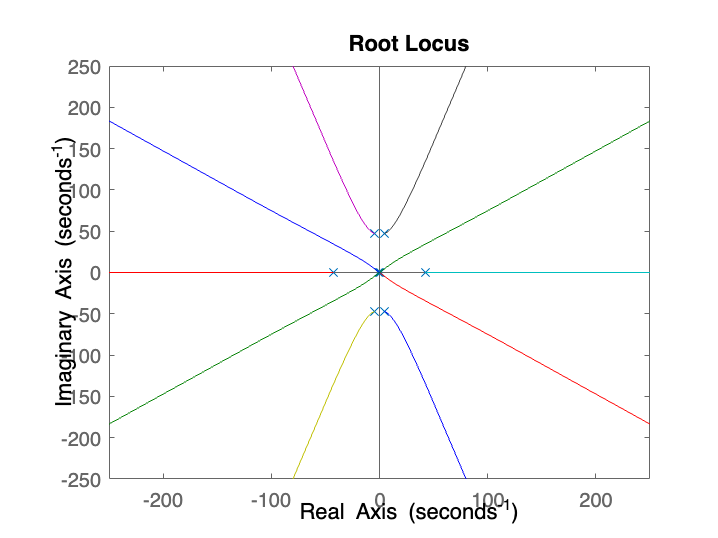

Freq=50;
Ts=1/Freq;

A=[0 0 1 0 ;0 0 0 1 ;(-Ks/Jm) (Ks/Jm) -((Km)^2/(Ra*Jm)) 0;(Ks/Jl) (-Ks/Jl-(m*g*l*cosd(30))/(Jl)) 0 0];
B=[0;0;Km/(Ra*Jm);0];
C=[0 1 0 0];
D=0;

A_aug1=[A zeros(4,1);C 0];
B_aug1=[B;0];
C_aug1=[C 0];
D_aug1=0;

G_disc=c2d(ss(A_aug1,B_aug1,C_aug1,D_aug1),Ts,'zoh');
A_aug=G_disc.A;
B_aug=G_disc.B;
C_aug=G_disc.C;
D_aug=G_disc.D;

C1=[0,0,0,0,1];
[num,den]=ss2tf(A_aug,B_aug,C1,D);
G_rho_plus=tf(num,den);
numG=([1.721e05]*[1.721e05]);
s=tf('s');
denG_plus=s^5 + 52.8*s^4 + 2668*s^3 + 9.688e04*s^2 + 7.08e04*s;
denG_minus=-s^5 + 52.8*s^4 - 2668*s^3 + 9.688e04*s^2 - 7.08e04*s;
denG=denG_plus*denG_minus;
sysGG=(numG/denG);
rlocus(sysGG);


rho=1.04e3;
%A1 answer: increasing magnitude of rho pushes CLP farther into LHP, ie requiring a
%larger control effort, 
Q_aug=rho*transpose(C1)*C1;
R=1;
[P,K,L]=idare(A_aug,B_aug,Q_aug,R); 
K_x=K(1:4);
K_I=K(end);

%%A2 answer: because the ratio of Q/R is what ultimately matters, increasing R, thus
%%decreasing the ratio, places a greater weight/emphasis on minimising the
%%control effort, whereas the opposite effect emphasises transient
%%performance
Q_riccati=1*eye(5);
Q_riccati(5,5)=10000;
R_riccati=1;
[P2,K2,L2]=idare(A_aug,B_aug,Q_riccati,R_riccati);
K_x2=K2(1:4);
K_I2=K2(end);

## B: LQG-Reduced Kalman Filter

A_11=A(1,1);
A_12=A(1,2:4);
A_21=A(2:4,1);
A_22=A(2:4,2:4);

B_1=B_aug(1,1);
B_2=B_aug(2:4,1);

W=1*eye(3); %%process noise. Increasing W bumps up observer gain as we are less sure of our model, and have to rely more on sensors
V=10; %% measurement noise. Increasing V decreases observer gains, as we are less sure of sensor measurements
%%if using 2 outputs, make V a 2x2

[P_d,K_d,eig_d]=icare(A_22',A_12',W,V);
L_d=transpose(K_d);

## Sinusoidal disturbance rejection

w=4*pi;
Ad_sine=[0 1;-w^2 0]; %%disturbance matrix for tracking ramp
Cd_sine=[1 0];

A_aug_sine=[A B*Cd_sine;zeros(2,4) Ad_sine];
B_aug_sine=[B;zeros(2,1)];
C_aug_sine=[C zeros(1,2)];

Wsine=1000*eye(6);
Vsine=1;

%%rearranging A
% rowOrderA = [5 6 1 2 3 4];
% A_aug_sine = A_aug_sine(rowOrderA, :);
% 
% columnOrderA = [5 6 1 2 3 4];
% A_aug_sine = A_aug_sine(:, columnOrderA)
% 
% rowOrderB = [5 6 1 2 3 4];
% B_aug_sine = B_aug_sine(rowOrderB, :);

% A_11_sine=A_aug_sine(1:2,1:2);
% A_12_sine=A_aug_sine(1:2,3:6);
% A_21_sine=A_aug_sine(3:6,1:2);
% A_22_sine=A_aug_sine(3:6,3:6);
% 
% B_1_sine=B_aug_sine(1:2,1);
% B_2_sine=B_aug_sine(3:6,1);

[Psine,Ksine,Esine]=icare(A_aug_sine',C_aug_sine',Wsine,Vsine);
Lsine=transpose(Ksine);

## Plots

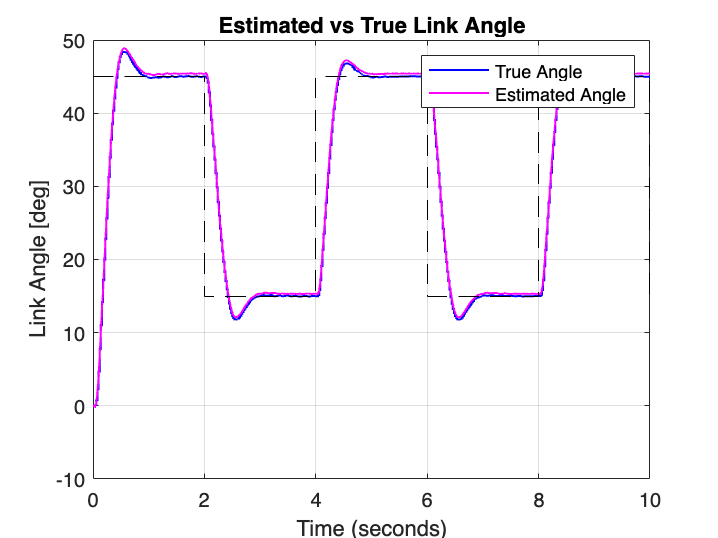

load('Error.mat');

load('y.mat')

load('reference.mat')

load('commandu.mat')

load('trueu.mat')

load('truestates.mat')

load('estimatedstates.mat')

load('disturbance_true.mat')

load('disturbance_est.mat')

load('theta_l_true.mat')

load('theta_l_estimate.mat')

load('KF_error.mat')

load('estimationerror.mat')

plot(theta_l_true,'b','LineWidth',1)
hold on
grid on
plot(theta_l_estimate,'m','LineWidth',1)
hold on
plot(reference,'k--','LineWidth',0.5)
title('Estimated vs True Link Angle')
ylabel('Link Angle [deg]')
legend('True Angle','Estimated Angle')
hold off

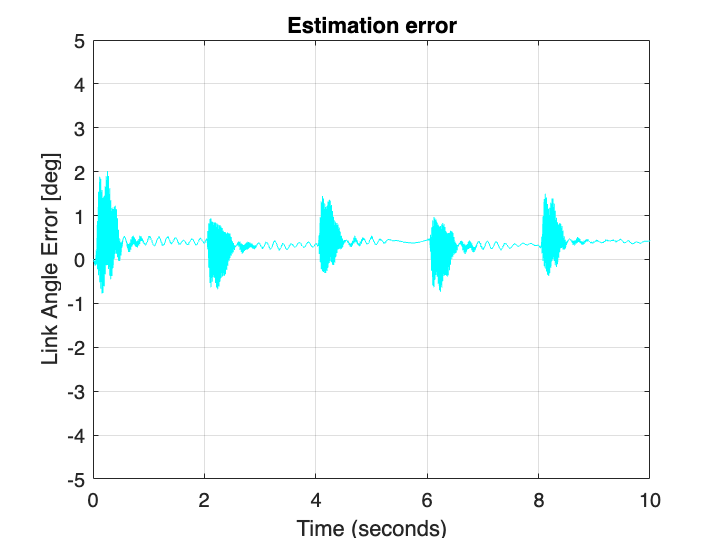


plot(KF_error,'c-','LineWidth',0.5)
grid on
title('Estimation error')
ylabel('Link Angle Error [deg]')
ylim([-5 5])
hold off

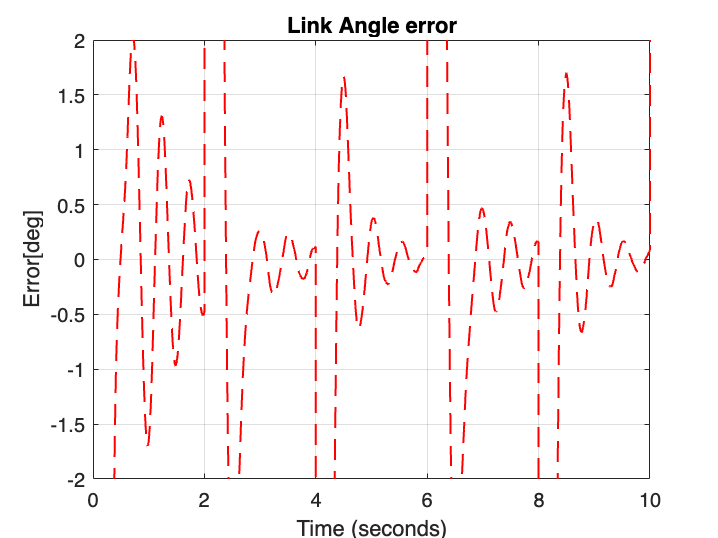



%%Task A plots


plot(Error,'r--','LineWidth',1)
grid on
ylabel('Error[deg]')
title('Link Angle error')
ylim([-2 2])

hold on
x = [0, 10];
y1 = [0.5, 0.5];
y2 = [-0.5, 0-.5];
% 
% plot(x, y1, 'k--');
% plot(x, y2, 'k--');
hold off

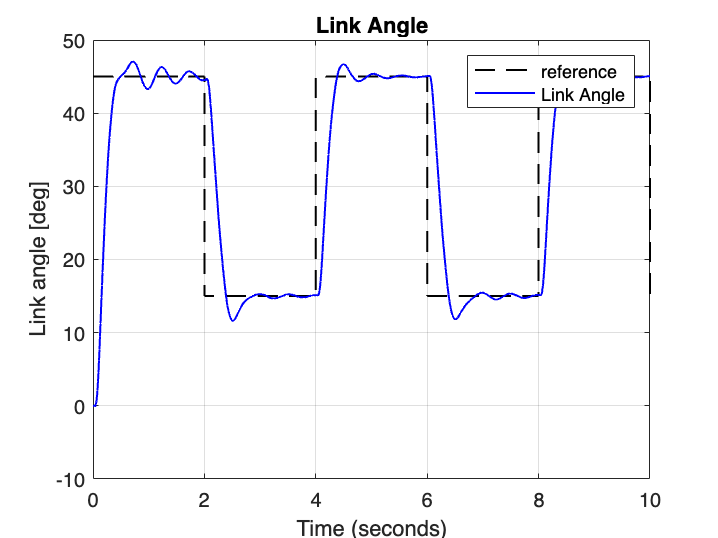


%%Task C plots
plot(reference,'k--','LineWidth',1)
hold on
grid on
plot(y,'b','LineWidth',1)
ylabel('Link angle [deg]')
title('Link Angle')
legend('reference','Link Angle')
hold off

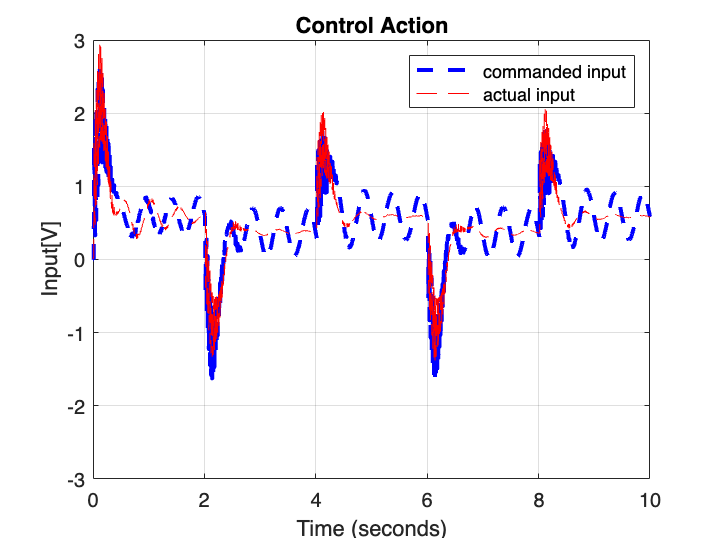


plot(commandu,'b--','LineWidth',2)
hold on
grid on
plot(trueu,'r--')
title('Control Action','LineWidth',2)
ylim([-3 3])
ylabel('Input[V]')
legend('commanded input','actual input')
hold off

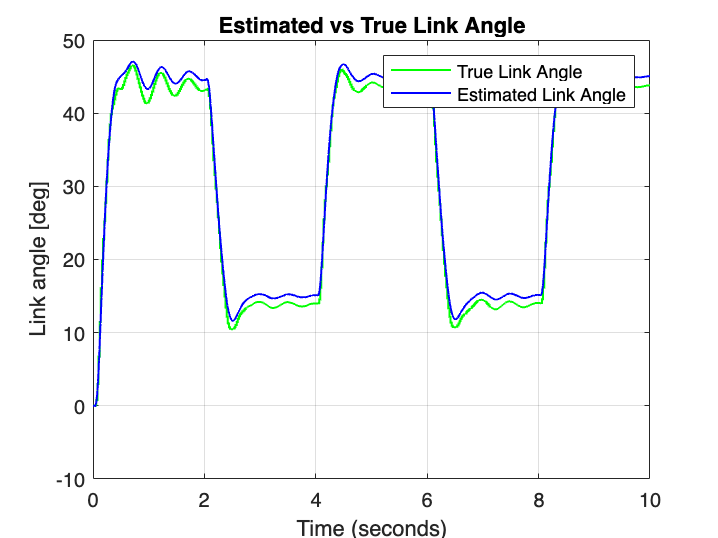


plot(truestates,'g','LineWidth',1)
hold on
grid on
plot(estimatedstates,'b','LineWidth',1)
ylabel('Link angle [deg]')
title('Estimated vs True Link Angle')
legend('True Link Angle','Estimated Link Angle')
hold off

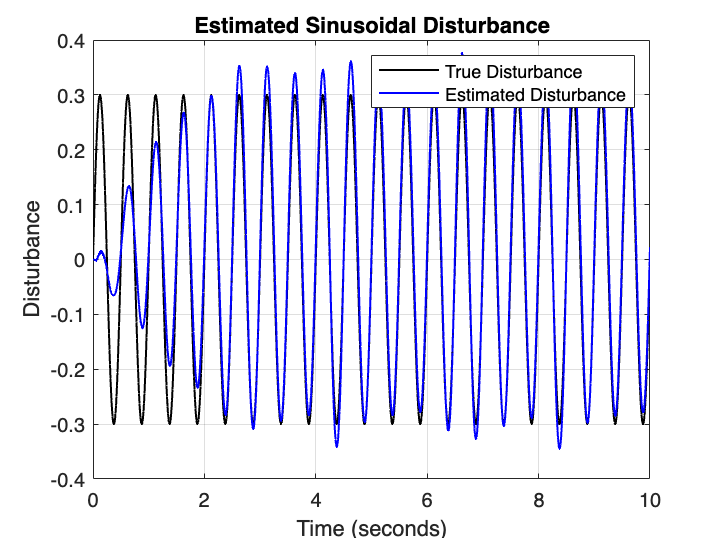


plot(disturbance_true,'k','LineWidth',1)
hold on
grid on
plot(disturbance_est,'b','LineWidth',1)
ylabel('Disturbance')
title('Estimated Sinusoidal Disturbance')
legend('True Disturbance','Estimated Disturbance')
hold off

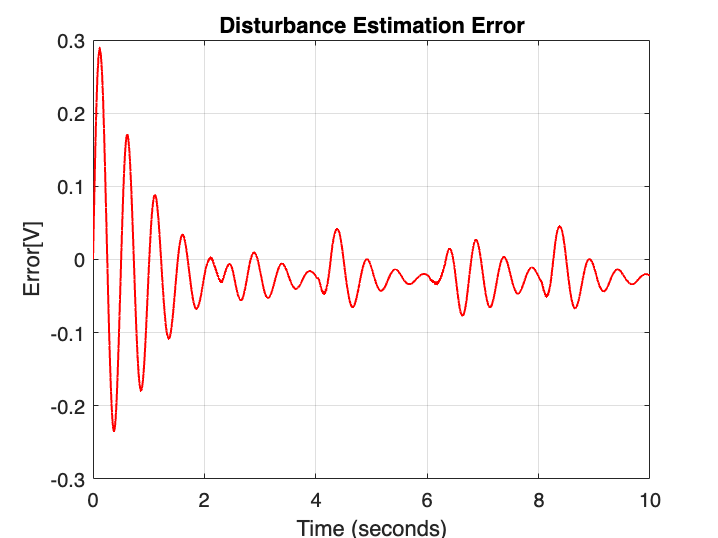


plot(estimationerror,'r','LineWidth',1)
ylabel('Error[V]')
grid on
title('Disturbance Estimation Error')
hold off